a = 1.1;
params.K_BN = 250;      
params.K_HN = 50;      
params.K_HM = 30;      
params.Y_B = 0.5;        
params.Y_HN = 0.5;     
params.Y_HM = 1;       
params.delta_N = 0.3;  
params.alpha = 5;
params.gamma = 0.1;
params.Ncrit = 20;     
params.h = 8;   
% params.mu_B = 0.2; 
% params.mu_H = 1;   
params.delta_A = 0.1;
params.K_BD = 1;
params.K_CD = 1;
params.epsilon = 0.6;
params.kappa = 2;
params.Y_BD = 1;
params.Y_CD = 1;

% ---------------------------------------------------------
% Additional parameters needed after introducing species C (set similar to H)
% ---------------------------------------------------------

% [Growth rate parameter]
% Note: Original code did not specify mu_B and mu_H; mu_C is added here.
% Recommendation: Set initial value of params.mu_C identical to params.mu_H.
params.mu_C = 0.3; % Adjust this value based on your actual mu_H

% [Half-saturation constants (Monod constants)]
params.K_CN = 50;  % Half-saturation constant of C for N (reference params.K_HN = 50)
params.K_CM = 30;  % Half-saturation constant of C for M (reference params.K_HM = 30)

% [Yield coefficients]
params.Y_CN = 0.5; % Yield coefficient of C from N (reference params.Y_HN = 2)
params.Y_CM = 1;   % Yield coefficient of C from M (reference params.Y_HM = 1)

% [Interaction / Mortality parameters]
% Scenario 1 (B kills C): Require both parameters below.
% Scenario 2 (B cannot kill C): Set params.kappa_C to 0.
params.kappa_C = 2;      % Killing rate constant of antimicrobial A on C (reference params.kappa = 0.02)
params.epsilon_C = 0.6;  % Conversion efficiency of dead C into debris D (reference params.epsilon = 0.6)

% Initial conditions and time span
N0 = 500; B0 = 1; M0 = 10; H0 = 5;
tspan = [0 150];
y0_co = [N0; B0; H0; M0; 0; 0; 1];

% 2. Set parameter sweep ranges
mu_B_range = 0.1:0.05:5;
mu_H_range = 0.1:0.05:5;

num_mu_B = length(mu_B_range);
num_mu_H = length(mu_H_range);

% 3. Initialize storage matrices
% B_matrix: 2D matrix (rows: mu_H, columns: mu_B)
B_matrix = zeros(num_mu_H, num_mu_B);

% result_final_matrix: 3D matrix (3rd dimension length = 6), storing:
% [B_co, H_co, B_mono, cum_self_final_co, cum_self_final_mono, C_co]
result_final_matrix = zeros(num_mu_H, num_mu_B, 6);

% 4. Double loop for parameter sweep
disp('Starting parameter sweep, please wait...');

Starting parameter sweep, please wait...


for i = 1:num_mu_H
    for j = 1:num_mu_B
        % Extract current mu_B and mu_H values
        current_mu_H = mu_H_range(i);
        current_mu_B = mu_B_range(j);
        
        params.mu_H = current_mu_H;
        params.mu_B = current_mu_B;
        
        result = model_output_kill(params);
        
        % Save biomass difference (B_co - B_mono)
        B_matrix(i, j) = result(1) - result(3);
        
        % Save complete output vector
        result_final_matrix(i, j, :) = result;
    end
end
disp('Parameter sweep completed!');

Parameter sweep completed!


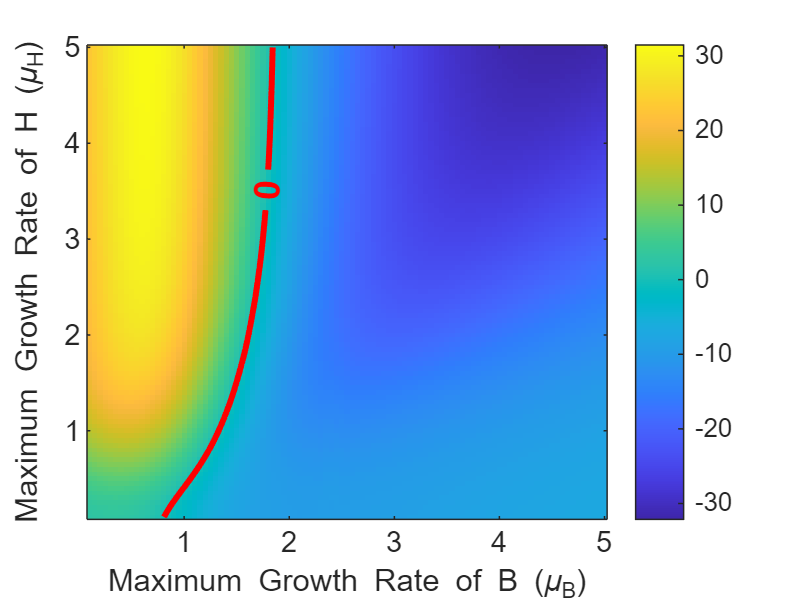


% 5. Plot heatmap of (B_co - B_mono) with 0-boundary contour
figure;
imagesc(mu_B_range, mu_H_range, B_matrix);
set(gca, 'YDir', 'normal'); % Set Y-axis direction ascending upwards
colormap(parula);           % Can be changed to 'jet' or 'turbo'
colorbar;

% Add boundary contour line where B_co - B_mono = 0
hold on;
[C, h_contour] = contour(mu_B_range, mu_H_range, B_matrix, [0 0], 'LineColor', 'r', 'LineWidth', 2);
clabel(C, h_contour, 'FontSize', 12, 'Color', 'r', 'FontWeight', 'bold');
hold off;

xlabel('Maximum Growth Rate of B (\mu_B)');
ylabel('Maximum Growth Rate of H (\mu_H)');